# Heart Attack Project Code

## Feature Analysis and Plots

h_data = readmatrix("processedcleveland_ind.csv"); 
data = h_data

data =    63.0000    1.0000    1.0000         0         0  145.0000  233.0000    1.0000    1.0000  150.0000         0    2.3000         0    1.0000         0         0         0    1.0000         0         0
   67.0000    1.0000         0         0         0  160.0000  286.0000         0    1.0000  108.0000    1.0000    1.5000         0         0         0         0    1.0000         0         0    1.0000
   67.0000    1.0000         0         0         0  120.0000  229.0000         0    1.0000  129.0000    1.0000    2.6000         0         0         0    1.0000         0         0    1.0000    1.0000
   37.0000    1.0000         0         0    1.0000  130.0000  250.0000         0         0  187.0000         0    3.5000         0    1.0000         0         0         0         0         0         0
   41.0000         0         0    1.0000         0  130.0000  204.0000         0    1.0000  172.0000         0    1.4000    1.0000         0         0         0         0         0         


% 5 random examples and all the feature names 
head(h_data, 5)

   63.0000    1.0000    1.0000         0         0  145.0000  233.0000    1.0000    1.0000  150.0000         0    2.3000         0    1.0000         0         0         0    1.0000         0         0
   67.0000    1.0000         0         0         0  160.0000  286.0000         0    1.0000  108.0000    1.0000    1.5000         0         0         0         0    1.0000         0         0    1.0000
   67.0000    1.0000         0         0         0  120.0000  229.0000         0    1.0000  129.0000    1.0000    2.6000         0         0         0    1.0000         0         0    1.0000    1.0000
   37.0000    1.0000         0         0    1.0000  130.0000  250.0000         0         0  187.0000         0    3.5000         0    1.0000         0         0         0         0         0         0
   41.0000         0         0    1.0000         0  130.0000  204.0000         0    1.0000  172.0000         0    1.4000    1.0000         0         0         0         0         0         0      


% DATA SIZE: (303 x 14)

% m = 14;
% columnNames = data.Properties.VariableNames;
% commenting out for now
columnNames = {'age', 'sex', 'cp1', 'cp2', 'cp3', 'trtbps', 'chol', 'fbs', 'restecg', 'thalachh', 'exng', 'oldpeak', 'slp1', 'slp3', 'caa1', 'caa2', 'caa3', 'thall6', 'thall7', 'output'};


% Missing Values
missingCounts = sum(ismissing(data));
disp('Missing Values per Column:');

Missing Values per Column:


for i = 1:length(columnNames)
   fprintf('%-15s: %d\n', columnNames{i}, missingCounts(i));
end

age            : 0
sex            : 0
cp1            : 0
cp2            : 0
cp3            : 0
trtbps         : 0
chol           : 0
fbs            : 0
restecg        : 0
thalachh       : 0
exng           : 0
oldpeak        : 0
slp1           : 0
slp3           : 0
caa1           : 0
caa2           : 0
caa3           : 0
thall6         : 0
thall7         : 0
output         : 0



% Feature Distribution
% This  may take a while to run
% for i = 1 : m
%     plotHistogram(h_data(:, i), columnNames{i})
% end
disp('Histograms Complete!')

Histograms Complete!





% Feature Scaling

## Initializing Data

% Initialize Data
X = h_data(:, 1:end-1);
[m,n] = size(X);
X = [ones(m,1), X];
y = h_data(:,end);

% Train Test Split
X_rand = X(randperm(size(X, 1)), :);
y_rand = y(randperm(size(y, 1)), :);

% Correlation Matrix
corrcoef(X_rand)

ans =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN    1.0000   -0.0924    0.0426   -0.1632   -0.0432    0.2905    0.2026    0.1321    0.1393   -0.3946    0.0965    0.1971   -0.1840    0.0256    0.1719    0.2225    0.1594    0.0597    0.1038
       NaN   -0.0924    1.0000    0.0925   -0.0419   -0.1151   -0.0663   -0.1981    0.0389    0.0460   -0.0605    0.1436    0.1066   -0.0154    0.0502    0.1046   -0.0155    0.0708    0.1454    0.3277
       NaN    0.0426    0.0925    1.0000   -0.1288   -0.1804    0.1499   -0.0570    0.0598    0.0679    0.0804   -0.0943    0.0836   -0.0445    0.0675   -0.0620    0.0399   -0.0779    0.0320   -0.0234
       NaN   -0.1632   -0.0419   -0.1288    1.0000   -0.2768   -0.0808   -0.0177   -0.0540   -0.0923    0.2561   -0.2322   -0.2830    0.2376   -0.0518   -0.0598   -0.0888   -0.0832   -0.0369

% Plot

train = .6;
cv = .2;
% test = .2;


train_split = round(m*train);
cv_split = round(m*cv);
% test_split = round(m*test);


X_train = X_rand(1:train_split,:);
X_cv = X_rand(train_split:train_split+cv_split,:);
X_test = X_rand(train_split+cv_split:m,:);

y_train = y_rand(1:train_split,:);
y_cv = y_rand(train_split:train_split+cv_split,:);
y_test = y_rand(train_split+cv_split:m,:);

## Logistic Regression (LR) Gradient Descent

% Function Calls
initial_theta = zeros(n+1,1);

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, cost] = ...
    fminunc(@(t)(costFunctionLR(t, X, y)), initial_theta, options);


Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>



fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.308510



fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 -2.583759 
 -0.023349 
 1.654673 
 -2.379669 
 -0.927470 
 -1.984784 
 0.027986 
 0.004478 
 -0.584794 
 0.473858 
 -0.019905 
 0.651561 
 0.402449 
 -1.298345 
 -0.688428 
 2.242172 
 3.259859 
 2.215312 
 -0.160135 
 1.429515 


% Accuracy Checking

p_train = predictLog(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 50.561798



p_test = predictLog(theta, X_test);
test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

Test Accuracy: 60.655738


p_cv = predictLog(theta, X_cv);
cv_accuracy = mean(double(p_cv == y_cv)) * 100;
fprintf('Cross Validation Accuracy: %f\n', cv_accuracy);

Cross Validation Accuracy: 50.000000


## Regularized Logistic Regression (RLR) Gradient Descent

% Function Calls
initial_theta = zeros(n+1,1);

% Initialize fitting parameters
initial_theta = zeros(size(X_train, 2), 1);

% Set regularization parameter lambda
lambda = 5;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = ...
        fminunc(@(t)(costFunctionRLR(t, X, y, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.308510


fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 -0.651485 
 0.000625 
 0.774672 
 -0.599821 
 -0.346022 
 -0.826161 
 0.014157 
 0.003269 
 -0.141272 
 0.280750 
 -0.024442 
 0.546886 
 0.418331 
 -0.393435 
 -0.183824 
 0.788072 
 0.899631 
 0.448900 
 0.087074 
 1.012228 


% Accuracy Checking

p_train = predictLog(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 47.752809


p_test = predictLog(theta, X_test);
test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

Test Accuracy: 63.934426


p_cv = predictLog(theta, X_cv);
cv_accuracy = mean(double(p_cv == y_cv)) * 100;
fprintf('Cross Validation Accuracy: %f\n', cv_accuracy);

Cross Validation Accuracy: 50.000000


## Logistic Regression (LR) Cost Function

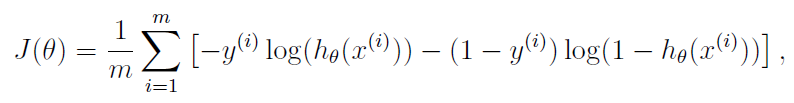

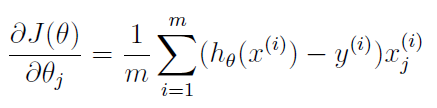

%=====================================================================================================%
function [J, grad] = costFunctionLR(theta, X, y)

m = length(y);

% J = 0;
% grad = zeros(size(theta));

h = sigmoid(X*theta);

J = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));

grad = (1/m) * (X' * (h - y));

end
%=====================================================================================================%

## Regularized Logistic Regression (RLR) Cost Function

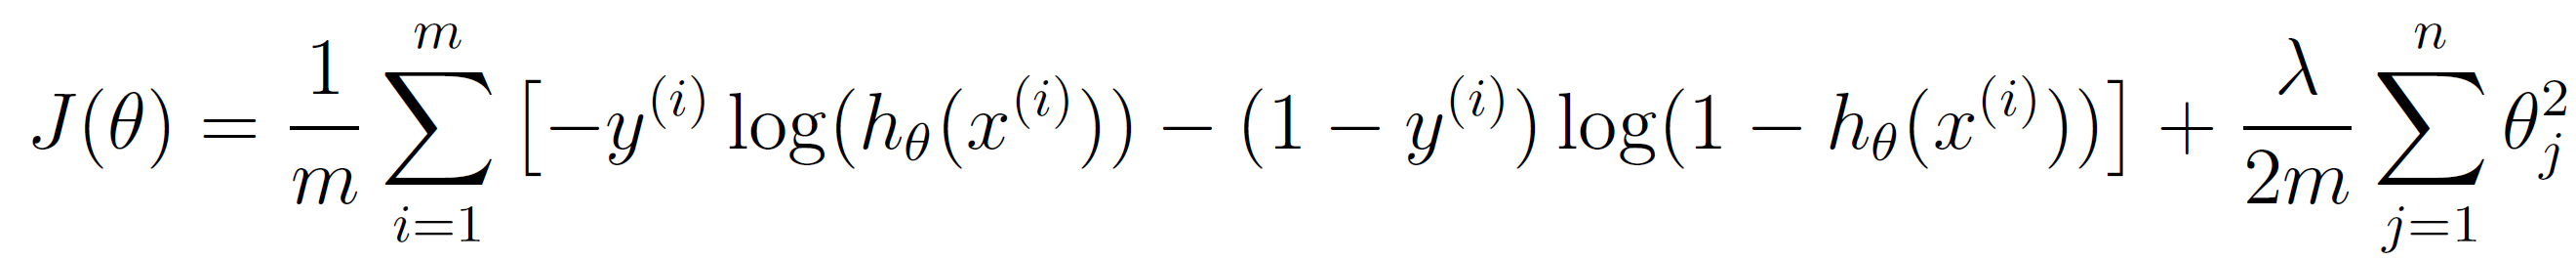

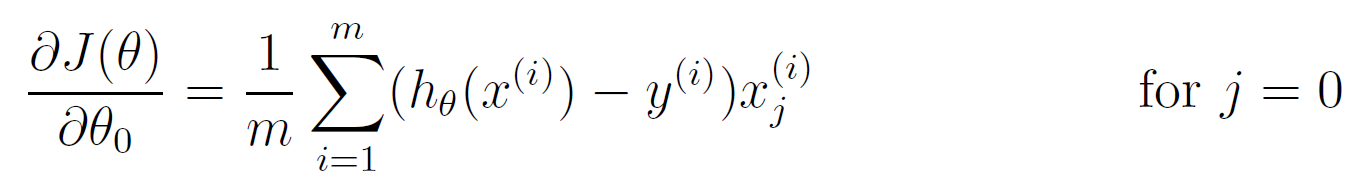

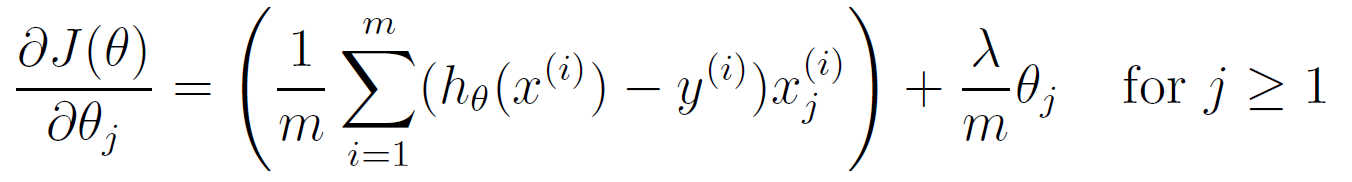

%=====================================================================================================%
function [J, grad] = costFunctionRLR(theta, X, y, lambda)

m = length(y); % number of training examples
 
% J = 0;
% grad = zeros(size(theta));

h = sigmoid(X*theta);

J = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));
J = J + (lambda/(2*m)) * sum(theta(2:end).^2);

grad = (1/m) * (X' * (h - y));
grad(2:end) = grad(2:end) + (lambda/m) * theta(2:end);

end

%=====================================================================================================%

## Sigmoid Function

%=====================================================================================================%
function g = sigmoid(z)

g = zeros(size(z));
g = 1./(1+exp(-z)); %g = 1./(1+e.^(-z))

end
%=====================================================================================================%

## Predict Function Logistic Regression

%=====================================================================================================%
function p = predictLog(theta, X)

m = size(X,1);
p = zeros(m, 1);

h = sigmoid(X*theta);
p(h>=0.5) = 1;

end
%=====================================================================================================%

## Plot Histogram

%=====================================================================================================%
function plotHistogram(data, plotTitle)
    % plotHistogram creates a histogram for the input data array with a title.
    % Inputs:
    %   - data: Array of numeric data to be visualized in the histogram
    %   - plotTitle: String for the title of the plot

    % Create the histogram
    histogram(data, 'NumBins', 30, 'FaceColor', 'blue', 'EdgeColor', 'black');

    % Customize the appearance
    xlabel('Data Values');
    ylabel('Frequency');
    title(plotTitle);
    grid on;
end
%=====================================================================================================%